Importing S&P 500 Daily time series

spx = readmatrix('../data/spx_daily_11-21.csv');
spx = fliplr(transpose(spx(:,2)));
idx = 1:length(spx);
disp("S&P 500 Daily: (length: "+length(spx)+")")

S&P 500 Daily: (length: 2560)


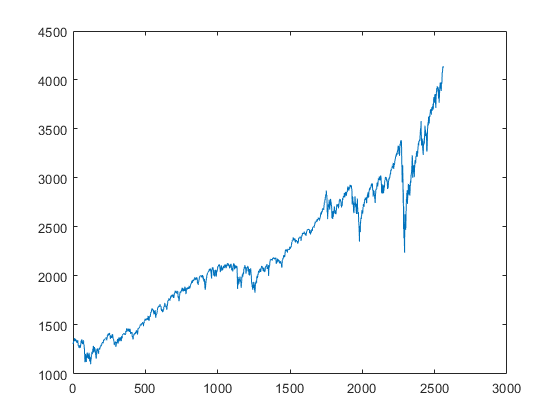

plot(idx,spx)

Now we look at the clusters of the four data matrizes (sts_target,sts_opposed,whole_target,whole_opposed) calculated for different r,k,w values for the Bitcoin as target time series.

normMethods = ["none" "zscore" "norm" "scale" "range" "medianiqr"];
distMetrics = ["eukl" ""];
clusterAlgos = ["kmeans" "agglo" "gmm"];

%%%%%%%%%%%%%%%%%
n = 1;
r = 3;

k = 11;
w = 32;

unify = true;
clusterAlgo = clusterAlgos(3);
%%%%%%%%%%%%%%%%%

normMethod = normMethods(2);
distM = distMetrics(1);
reducedSampling = true;
dimRed = true;
seed_ = 0;

target_ts = spx;
opposing_ts = createRandomWalk(target_ts, seed_);



meaningfulness_sts = 0;
meaningfulness_whole = 0;

sts_target_matrix = toStsMatrix(target_ts, w);
sts_opposing_matrix = toStsMatrix(opposing_ts, w);

whole_target_matrix = toRandomSamplingMatrix(target_ts, w, reducedSampling, seed_);
whole_opposing_matrix = toRandomSamplingMatrix(opposing_ts, w, reducedSampling, seed_);

sts_target_matrix = scaleFeatureMatrix(sts_target_matrix, normMethod);
sts_opposing_matrix = scaleFeatureMatrix(sts_opposing_matrix, normMethod);

whole_target_matrix = scaleFeatureMatrix(whole_target_matrix, normMethod);
whole_opposing_matrix = scaleFeatureMatrix(whole_opposing_matrix, normMethod);


if dimRed 
    sts_target_matrix = dimReduction(sts_target_matrix, 90);
    sts_opposing_matrix = dimReduction(sts_opposing_matrix, 90);

    whole_target_matrix = dimReduction(whole_target_matrix, 90);
    whole_opposing_matrix = dimReduction(whole_opposing_matrix, 90);
end


w_sts = min(size(sts_target_matrix, 2), size(sts_opposing_matrix, 2));
w_whole = min(size(whole_target_matrix, 2), size(whole_opposing_matrix, 2));

sts_target_matrix = sts_target_matrix(:,1:w_sts);
sts_opposing_matrix = sts_opposing_matrix(:,1:w_sts);

whole_target_matrix = whole_target_matrix(:,1:w_whole);
whole_opposing_matrix = whole_opposing_matrix(:,1:w_whole);

for z = 1:n
    sts_target_centers = zeros(k,w_sts);
    sts_opposing_centers = zeros(k,w_sts);
       
    whole_target_centers = zeros(k,w_whole);
    whole_opposing_centers = zeros(k,w_whole);

    for i = 1:r
        sts_target_centers(:,:,i) = clusterFunctions(sts_target_matrix,k,clusterAlgo,unify);
        sts_opposing_centers(:,:,i) = clusterFunctions(sts_opposing_matrix,k,clusterAlgo,unify);
        
        whole_target_centers(:,:,i) = clusterFunctions(whole_target_matrix,k,clusterAlgo,unify);
        whole_opposing_centers(:,:,i) = clusterFunctions(whole_opposing_matrix,k,clusterAlgo,unify);    
        
    end
    %disp(whole_target_centers);
    disp('STS')
    meaningfulness_sts = meaningfulness_sts + clusteringMeaningfulness(sts_target_centers, sts_opposing_centers, distM);
    disp('~~~~~~~~~')
    disp('WHOLE')
    meaningfulness_whole = meaningfulness_whole + clusteringMeaningfulness(whole_target_centers, whole_opposing_centers, distM);
end

STS


wsd:10.49
bsd:23.43


~~~~~~~~~


WHOLE


wsd:17.3
bsd:31.86


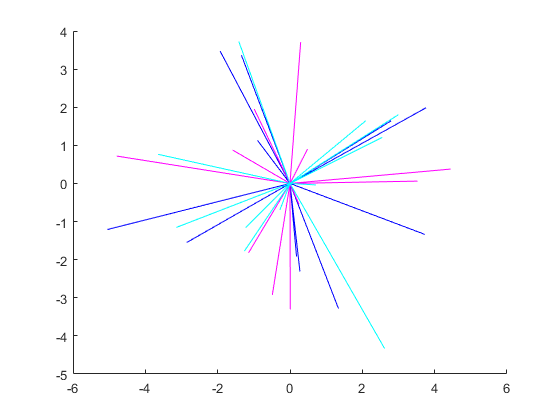

meaningfulness_sts = meaningfulness_sts/n;
meaningfulness_whole = meaningfulness_whole/n;

% disp('--------------------------------------------------------------------------');    
% disp('STS target centers:');
% disp('');
% disp(sts_target_centers);
% disp('--------------------------------------------------------------------------');
% disp('STS opposing centers:');
% disp('');
% disp(sts_opposing_centers);
% disp('--------------------------------------------------------------------------');
% disp('Whole target centers:');
% disp('');
% disp(whole_target_centers);
% disp('--------------------------------------------------------------------------');
% disp('Whole opposing centers:');
% disp('');
% disp(whole_opposing_centers);
% disp('--------------------------------------------------------------------------');
% disp('');
% disp('sts meaning: ');
% disp((meaningfulness_sts/n));
% disp('whole meaning: ');
% disp((meaningfulness_whole/n));

%%%%%% visualize %%%%%%
n_comp = 2;

pca_sts_target_centers = zeros(k,n_comp,r);
pca_sts_opposing_centers = zeros(k,n_comp,r);
pca_whole_target_centers = zeros(k,n_comp,r);
pca_whole_opposing_centers = zeros(k,n_comp,r);

pca_sts_target_var = zeros(r,n_comp);
pca_sts_opposing_var = zeros(r,n_comp);
pca_whole_target_var = zeros(r,n_comp);
pca_whole_opposing_var = zeros(r,n_comp);
    
for i = 1:r
    [~,score,~,~,var,~] = pca(sts_target_centers(:,:,i), 'NumComponents', n_comp);
    pca_sts_target_centers(:,:,i) = score;
    pca_sts_target_var(i,:) = var(1:n_comp);
    
    [~,score,~,~,var,~] = pca(sts_opposing_centers(:,:,i), 'NumComponents', n_comp);
    pca_sts_opposing_centers(:,:,i) = score;
    pca_sts_opposing_var(i,:) = var(1:n_comp);
    
    [~,score,~,~,var,~] = pca(whole_target_centers(:,:,i), 'NumComponents', n_comp);
    pca_whole_target_centers(:,:,i) = score;
    pca_whole_target_var(i,:) = var(1:n_comp);
    
    [~,score,~,~,var,~] = pca(whole_opposing_centers(:,:,i), 'NumComponents', n_comp);
    pca_whole_opposing_centers(:,:,i) = score;
    pca_whole_opposing_var(i,:) = var(1:n_comp);
    
end

% disp('--------------------------------------------------------------------------')    
% disp('STS target centers:')
% disp('')
% disp(pca_sts_target_centers)
% disp('____')
% disp(pca_sts_target_var)
% disp('--------------------------------------------------------------------------')
% disp('STS opposing centers:')
% disp('')
% disp(pca_sts_opposing_centers)
% disp('____')
% disp(pca_sts_opposing_var)
% disp('--------------------------------------------------------------------------')
% disp('Whole target centers:')
% disp('')
% disp(pca_whole_target_centers)
% disp('____')
% disp(pca_whole_target_var)
% disp('--------------------------------------------------------------------------')
% disp('Whole opposing centers:')
% disp('')
% disp(pca_whole_opposing_centers)
% disp('____')
% disp(pca_whole_opposing_var)
% disp('--------------------------------------------------------------------------')
% disp('')

%colors = ['y','m','c','r','g','b','k'];
colors = ['b','m','c','r','g','y','k'];
%colors = ['black','magenta','cyan','red','green','blue','orange','lightblue','pink','purple']

figure;
for i=1:size(pca_sts_target_centers,3)
    hold on;
    plotv(pca_sts_target_centers(:,:,i).', colors(i));
    hold off;
end

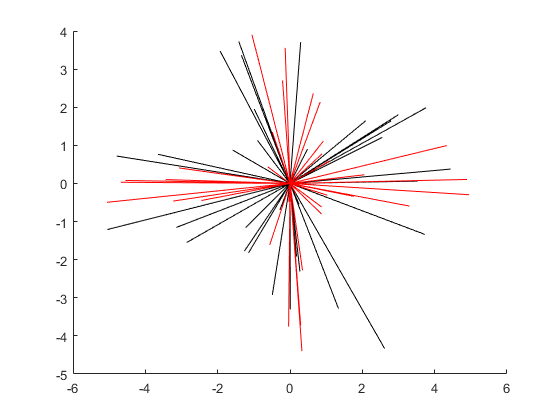


figure;
for i=1:size(pca_sts_target_centers,3)
    hold on;
    plotv(pca_sts_target_centers(:,:,i).', 'k');
    hold off;
end
for i=1:size(pca_sts_opposing_centers,3)
    hold on;
    plotv(pca_sts_opposing_centers(:,:,i).', 'r');
    hold off;
end

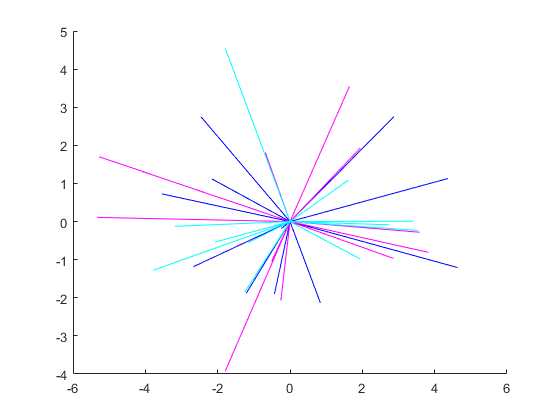


figure;
for i=1:size(pca_whole_target_centers,3)
    hold on;
    plotv(pca_whole_target_centers(:,:,i).', colors(i));
    hold off;
end

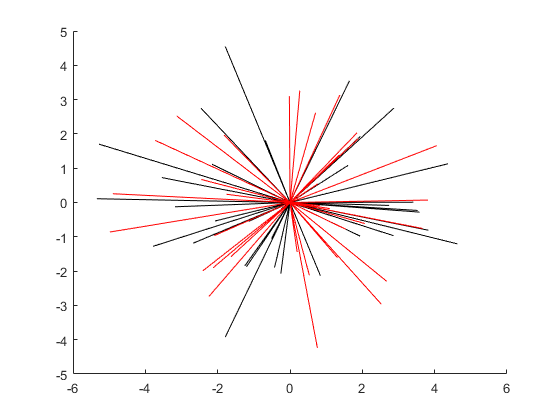


figure;
for i=1:size(pca_whole_target_centers,3)
    hold on;
    plotv(pca_whole_target_centers(:,:,i).', 'k');
    hold off;
end
for i=1:size(pca_whole_opposing_centers,3)
    hold on;
    plotv(pca_whole_opposing_centers(:,:,i).', 'r');
    hold off;
end